addpath('functions\');

% a. 1. Forward
imgs=prepare();

num_imgs = 6

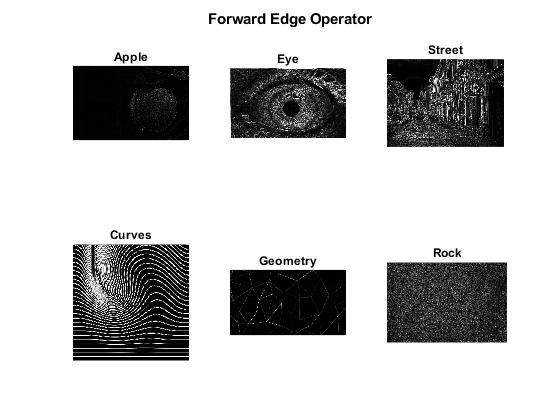

returned_imgs=cell(0);
for img = imgs
    img = cell2mat(img);
    kx=[-0.5 2 -1.5];
    ky=[-0.5;
        2;
       -1.5];
    cx=convolve_2d(img,kx);
    cy=convolve_2d(img,ky);
    c=euclidian_dist(cx,cy);
    
    
%     dil=dilate(c);
%     imshow(dil);
%     ero=erode(c);
%     imshow(ero);
    
%     imshow(c);
%     c(c>0.1)=1;
%     c(c~=1)=0;
%     thresholded=open_img(c);
%     imshow(thresholded);
%     
    returned_imgs{end+1}=c;
end

display_imgs('Forward Edge Operator',returned_imgs);

% a. 2. Backward
imgs=prepare();

num_imgs = 6

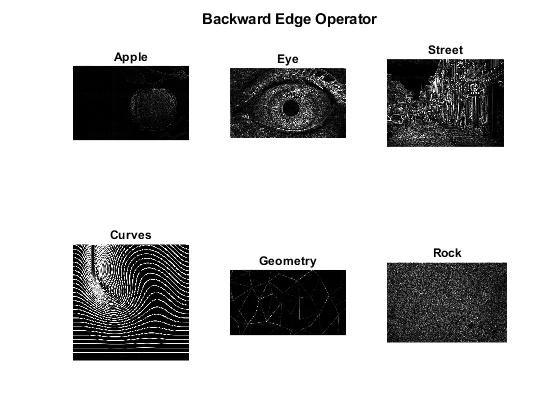

returned_imgs=cell(0);
for img = imgs
    img = cell2mat(img);
    kx=[1.5 -2 0.5];
    ky=[1.5;
        -2;
       0.5];
    cx=convolve_2d(img,kx);
    cy=convolve_2d(img,ky);
    c=euclidian_dist(cx,cy);
%     imshow(c);
    returned_imgs{end+1}=c;
    
end
display_imgs('Backward Edge Operator',returned_imgs);

% a. 3. Central
imgs=prepare();

num_imgs = 6

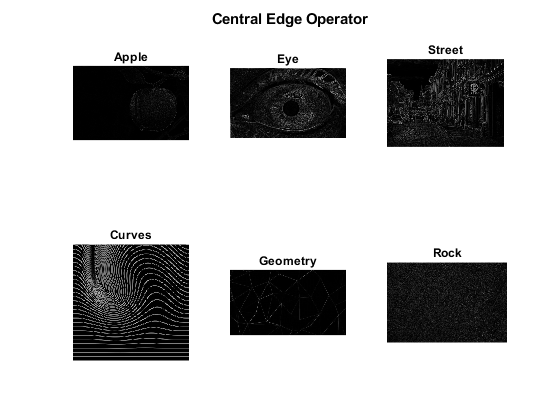

returned_imgs=cell(0);
for img = imgs
    img = cell2mat(img);
    kx=[0.5 0 -0.5];
    ky=[0.5;
        0;
       -0.5];
    cx=convolve_2d(img,kx);
    cy=convolve_2d(img,ky);
    c=euclidian_dist(cx,cy);
    returned_imgs{end+1}=c;
%     imshow(c);
end
display_imgs('Central Edge Operator',returned_imgs);

% b. Sobel operator
imgs=prepare();

num_imgs = 6

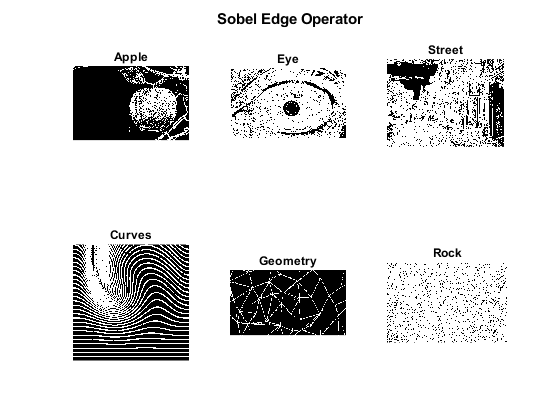

returned_imgs=cell(0);
for img = imgs
    img = cell2mat(img);
    kx = [-1 0 1; 
        -2 0 2;
        -1 0 1];
    
    ky = [1 2 1; 
         0 0 0;
        -1 -2 -1];
    
    cy=convolve_2d(img,ky);
    cx=convolve_2d(img,kx);
    c=euclidian_dist(cx,cy);
%     theta=atan2(cy,cx);
%     imshowpair(c,theta,'montage');
    c(c>0.1)=1;
    c(c~=1)=0;
    returned_imgs{end+1}=erode(c);
end
display_imgs('Sobel Edge Operator',returned_imgs);

% c. Prewitt operator
imgs=prepare();

num_imgs = 6

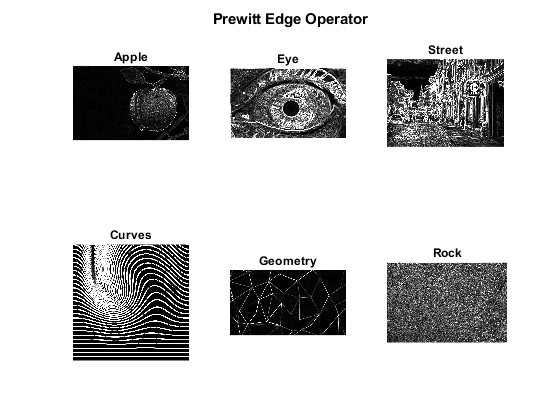

returned_imgs=cell(0);
for img = imgs
    img = cell2mat(img);
    
    kx = [-1 0 1;
          -1 0 1;
          -1 0 1];
      
    ky = [1 1 1; 
         0 0 0;
        -1 -1 -1];
    
    cy=convolve_2d(img,ky);
    cx=convolve_2d(img,kx);
    c=euclidian_dist(cx,cy);
    theta=atan2(cy,cx);
%     imshowpair(c,theta,'montage');
    returned_imgs{end+1}=c;
end
display_imgs('Prewitt Edge Operator',returned_imgs);

% d. Canny Operator
% Implementation help from: 
% https://www.mathworks.com/matlabcentral/fileexchange/46859-canny-edge-detection
imgs=prepare();

num_imgs = 6

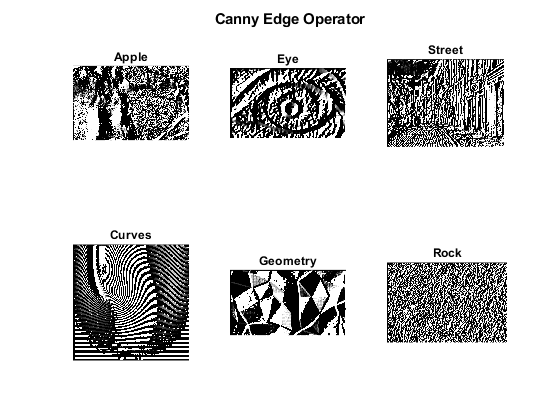

returned_imgs=cell(0);
for img = imgs
    img = cell2mat(img);
    sigma=2;
    N=ceil(6*sigma);
    k_g=gaussian_kernel(N,sigma);
    img_blurred=convolve_2d(img, k_g);
    
    kx = [-1 0 1; 
        -2 0 2;
        -1 0 1];
    
    ky = [1 2 1; 
         0 0 0;
        -1 -2 -1];
    
    img_blurred_x=convolve_2d(img_blurred, kx);
    img_blurred_y=convolve_2d(img_blurred, ky);
    
    G=euclidian_dist(img_blurred_x, img_blurred_y);
    theta=atan2(img_blurred_x, img_blurred_y);
    tt=theta;
    theta = theta * (180/pi);
    
    for i=1:size(img_blurred, 1)
        for j=1:size(img_blurred,2)
            if(theta(i,j) < 0)
                theta(i,j) = theta(i,j) + 360;
            end
        end
    end
    
new_img = zeros(size(img_blurred));    
for i=1:size(img_blurred,1)
    for j=1:size(img_blurred,2)
        if ((theta(i, j) >= 0 ) && (theta(i, j) < 22.5) || (theta(i, j) >= 157.5) && (theta(i, j) < 202.5) || (theta(i, j) >= 337.5) && (theta(i, j) <= 360))
            new_img(i, j) = 0;
        elseif ((theta(i, j) >= 22.5) && (theta(i, j) < 67.5) || (theta(i, j) >= 202.5) && (theta(i, j) < 247.5))
            new_img(i, j) = 45;
        elseif ((theta(i, j) >= 67.5 && theta(i, j) < 112.5) || (theta(i, j) >= 247.5 && theta(i, j) < 292.5))
            new_img(i, j) = 90;
        elseif ((theta(i, j) >= 112.5 && theta(i, j) < 157.5) || (theta(i, j) >= 292.5 && theta(i, j) < 337.5))
            new_img(i, j) = 135;
        end
    end
end

new_img2=zeros(size(img_blurred));
for i=2:size(img_blurred,1)-1
    for j=2:size(img_blurred,2)-1
        if (new_img(i,j)==0)
            new_img2(i,j) = (G(i,j) == max([G(i,j), G(i,j+1), G(i,j-1)]));
        elseif (new_img(i,j)==45)
            new_img2(i,j) = (G(i,j) == max([G(i,j), G(i+1,j-1), G(i-1,j+1)]));
        elseif (new_img(i,j)==90)
            new_img2(i,j) = (G(i,j) == max([G(i,j), G(i+1,j), G(i-1,j)]));
        elseif (new_img(i,j)==135)
            new_img2(i,j) = (G(i,j) == max([G(i,j), G(i+1,j+1), G(i-1,j-1)]));
        end
    end
end

T_Low = 0.075;
T_High = 0.175;

new_img2=new_img2.*G;
T_Low = T_Low * max(max(new_img2));
T_High = T_High * max(max(new_img2));

T_residue=zeros(size(img_blurred));

for i = 1:size(img_blurred,1)
    for j =1:size(img_blurred,2)
        if (new_img2(i, j) < T_Low)
            T_residue(i, j) = 0;
        elseif (new_img2(i, j) > T_High)
            T_residue(i, j) = 1;
        %Using 8-connected components
        elseif (new_img2(i+1,j)>T_High || new_img2(i-1,j)>T_High || new_img2(i,j+1)>T_High || new_img2(i,j-1)>T_High || new_img2(i-1, j-1)>T_High || new_img2(i-1, j+1)>T_High || new_img2(i+1, j+1)>T_High || new_img2(i+1, j-1)>T_High)
            T_residue(i,j) = 1;
        end
    end
end

edge_final = uint8(T_residue.*255);

% imshow(edge_final);
% returned_imgs{end+1}=tt;
returned_imgs{end+1}=edge_final;
    
end
display_imgs('Canny Edge Operator',returned_imgs);

% e. Laplacian operator
imgs=prepare();

num_imgs = 6

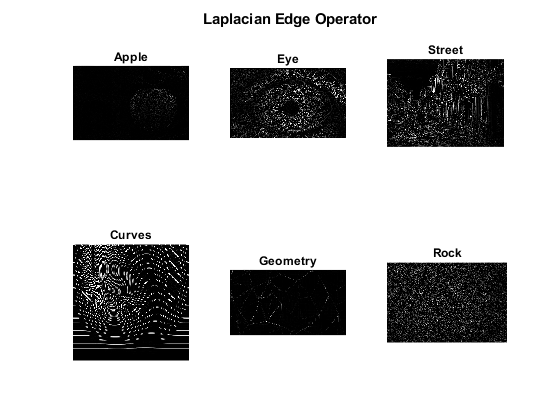

returned_imgs=cell(0);
for img = imgs
    img = cell2mat(img);
    k=[0 1 0;
       1 -4 1;
       0 1 0];
    c = convolve_2d(img, k);
%     imshow(c);
    returned_imgs{end+1}=c;
end
display_imgs('Laplacian Edge Operator',returned_imgs);

% f. Laplacian of Gaussian (LoG)
imgs=prepare();

num_imgs = 6

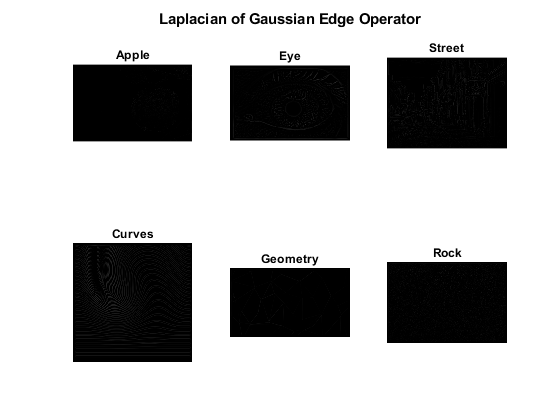

returned_imgs=cell(0);
for img = imgs
    img=cell2mat(img);
    img=padarray(img, [10,10], 'both');
    sigma=1.5;
    N=ceil(6*sigma);
    k=gaussian_kernel(N, sigma);
    c=convolve_2d(img, k);
    k_laplacian=[0 1 0;
                 1 -4 1;
                 0 1 0];
    c_laplacian=convolve_2d(c, k_laplacian);
%     imshow(c_laplacian);   
    returned_imgs{end+1}=c_laplacian;
end
display_imgs('Laplacian of Gaussian Edge Operator',returned_imgs);

% g. Difference of Gaussian (DoG)
imgs=prepare();

num_imgs = 6

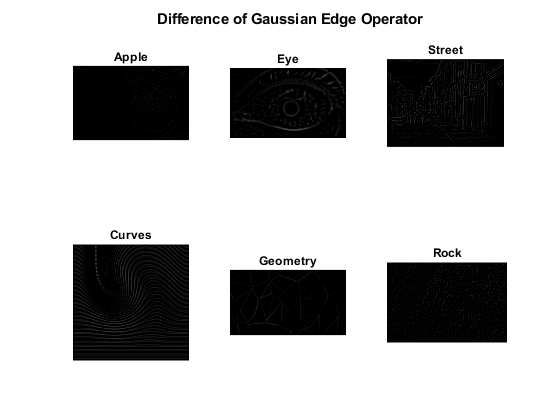

returned_imgs=cell(0);
for img = imgs
    img=cell2mat(img);
    s=1;
    k= 2^(s+1/s);
    
    sigma=2.5;
    N=ceil(6*sigma);
    k1=gaussian_kernel(N,k*sigma);
    
    k2=gaussian_kernel(N, sigma);
    
    k_DoG=k1-k2;
    
    c=convolve_2d(img, k_DoG);
%     imshow(c);
%      imhist(c);
    returned_imgs{end+1}=c;
end
display_imgs('Difference of Gaussian Edge Operator',returned_imgs);